% Cargar tabla desde el archivo CSV
Temp = readtable('emg_features_clustered.csv');

summary(Temp)


Temp: 472001×4 table

Variables:

    Activity: double
    Mobility: double
    Complexity: double
    Cluster: double

Statistics for applicable variables:

                  NumMissing     Min       Median       Max        Mean          Std    

    Activity          0           0        0.0016        1        0.0633        0.1189  
    Mobility          0           0        0.1695        1        0.2392        0.1737  
    Complexity        0           0        0.0470        1        0.1241        0.1458  
    Cluster           0           1             2        2        1.6018        0.4895  



whos Temp

  Name           Size               Bytes  Class    Attributes

  Temp      472001x4             15105793  table              



En MATLAB, el tipo de dato `float`** no existe** como tal. En cambio, los tipos de punto flotante que puedes usar son:

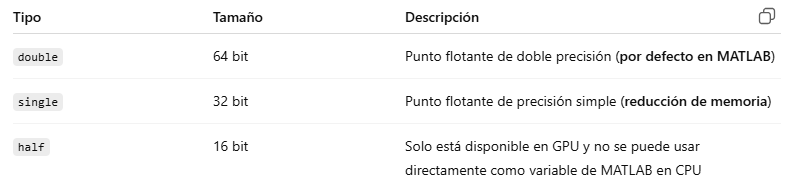

Temp.Activity   = half(Temp.Activity);
Temp.Mobility   = half(Temp.Mobility);
Temp.Complexity = half(Temp.Complexity);
if any(ismember(unique(Temp.Cluster), [1 2]))
    % Convierte 1 y 2 a valores booleanos
    Temp.Cluster = Temp.Cluster == 2;
else
    % Si no tiene 1 y 2, usa conversión estándar
    Temp.Cluster = boolean(Temp.Cluster);
end
summary(Temp)


Temp: 472001×4 table

Variables:

    Activity: half
    Mobility: half
    Complexity: half
    Cluster: logical (284046 true)

Statistics for applicable variables:

                  NumMissing       Min          Median         Max           Mean          Std    

    Activity          0          1×1 half      1×1 half      1×1 half      1×1 half      1×1 half 
    Mobility          0          1×1 half      1×1 half      1×1 half      1×1 half      1×1 half 
    Complexity        0          1×1 half      1×1 half      1×1 half      1×1 half      1×1 half 



whos Temp

  Name           Size              Bytes  Class    Attributes

  Temp      472001x4             3305768  table              



% Generar el resumen manualmente
fields = fieldnames(Temp);  % Obtener los nombres de los campos en Temp

Error using tabular/vertcat (line 207)
All tables being vertically concatenated must have the same number of variables.


for i = 1:length(fields)
    field = fields{i};
    data = Temp.(field);
    
    % Si es un arreglo numérico, calcula estadísticas
    if isnumeric(data)
        fprintf('\nResumen de %s:\n', field);
        fprintf('Número de elementos: %d\n', numel(data));
        fprintf('Promedio: %.6f\n', mean(data));
        fprintf('Desviación estándar: %.6f\n', std(data));
        fprintf('Valor mínimo: %.6f\n', min(data));
        fprintf('Valor máximo: %.6f\n', max(data));
        fprintf('Mediana: %.6f\n', median(data));
        fprintf('Rango intercuartil: %.6f - %.6f\n', prctile(data, 25), prctile(data, 75));
    % Si es un campo booleano (lógico), muestra un resumen
    elseif islogical(data)
        fprintf('\nResumen de %s (Booleano):\n', field);
        fprintf('Número de elementos: %d\n', numel(data));
        fprintf('Valor de "true": %d\n', sum(data));
        fprintf('Valor de "false": %d\n', numel(data) - sum(data));
    end
end

writetable(Temp, 'emg_features_optimized.csv');